% House Keeping
clear;
clc;

#### Errikos Flight Regime Sample

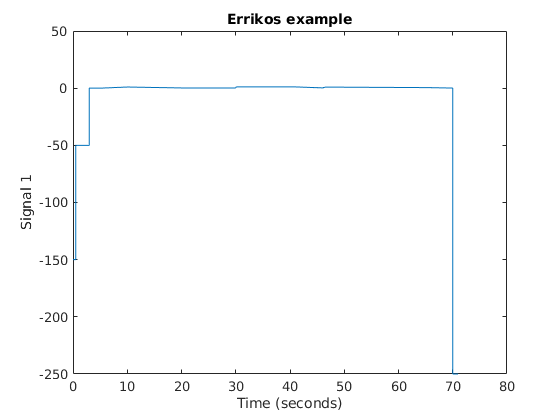

errikos_test = load("./Simulink Testing/samplemission.mat");
errikos_test = errikos_test.Scenario{1};

plot(errikos_test);
title("Errikos example");

#### Variables for Generating Flight Regimes

flightLen_max = 300;        % 5 mins
flightLen_min = 60;         % 1 min

sampleT = 0.005;            % from the Testing_Model simulink
samplingFreq = 1/sampleT; 

numberOfTests = 1000;       % number of flight regimes we will generate and test
random_pts_per_test = 70;   % how many points

% TBD
vel_limit = 4.5;              % if velocity is above this, the points are removed

#### Generating Flight Regimes

Parameters

flightReg_finalT = randi([flightLen_min, flightLen_max], 1, numberOfTests); % generating durations for the flight regimes
performance_array = zeros(1,numberOfTests);                                 % initializing performance array

Main Loop

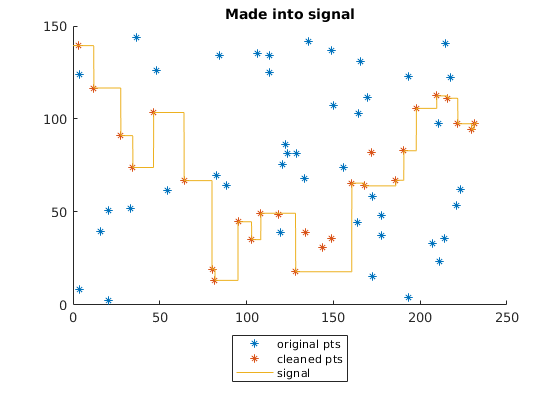

figure()
hold on

% Iterate over the generated flight regimes
% for i = 1:numberOfTests
for i = 1:1
    
    % Getting all the t_i for the current flight test
    %flightReg_time = [0:sampleT:flightReg_finalT(i)];

    random_time = sort(rand(1,random_pts_per_test) * flightReg_finalT(i));
    random_height =  rand(1,random_pts_per_test) * 144;

    % Duration of each section is rounded to the closest sampleT
    for j = 1:length(random_time)
        random_time(j) = round(random_time(j)/sampleT)*sampleT;
    end
    
    [fixed_time_array, fixed_height_array] = remove_large_vel(random_time, ...
                                                             random_height, ...
                                                             vel_limit);

    [flightReg_time, flightReg_DesiredHeight] = get_flight_regime(fixed_time_array, ...
                                                              fixed_height_array, ...
                                                              sampleT, ...
                                                              flightReg_finalT(i));

    %{
    % Get the real height using the physics model and controller

    realHeight_array = .....
    
    % Getting MSE of our tracking in this flight regime
    iteration_meanSquareError = getPerformance(flightReg_DesiredHeight, realHeight_array)
    
    performance_array(i) = iteration_meanSquareError;
    %}
    
  
    % Plotting generated random datapoints
    plot(random_time, random_height, "*");
    title("Original random points")
    
    % Plotting with removed large acceleration
    plot(fixed_time_array, fixed_height_array, "*")
    title("Removed large acceleration")
    
    % Plotting final signal
    plot(flightReg_time, flightReg_DesiredHeight)
    title("Made into signal")
    
    legend("original pts", "cleaned pts", "signal", "Location", "southoutside")

end
hold off

#### Controller Analysis

% Get overall performance for this controller 
% (i.e. mean of "performance_array", variance, ...)

% mean_perf = mean(performance_array);
% ...

#### Saving results

%save('test_controllerX', 'flightReg_finalT', 'performance_array')

For debugging

% Saving for debugging later
temp_t = random_time;
temp_h = random_height;

#### Debugging

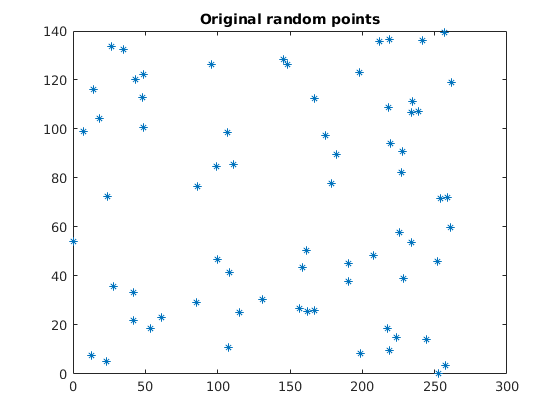

random_time = temp_t;
random_height = temp_h;
plot(temp_t, temp_h, "*")
title("Original random points")

[fixed_time_array, fixed_height_array] = remove_large_vel(random_time, ...
                                                             random_height, ...
                                                             vel_limit);

Removed idx 2
Idx = 2; velocity = -3.796214; accell = -0.310022
Removed idx 3
Removed idx 3
Idx = 3; velocity = -0.228874; accell = 0.332929
Removed idx 4
Removed idx 4
Removed idx 4
Removed idx 4
Idx = 4; velocity = 0.912658; accell = 0.062209
Removed idx 5
Removed idx 5
Removed idx 5
Removed idx 5
Removed idx 5
Idx = 5; velocity = -0.275044; accell = -0.101730
Idx = 6; velocity = 0.606661; accell = 0.116705
Idx = 7; velocity = 0.237629; accell = -0.015143
Removed idx 8
Removed idx 8
Idx = 8; velocity = 4.025223; accell = 0.274165
Removed idx 9
Idx = 9; velocity = 1.784986; accell = -0.283754
Removed idx 10
Removed idx 10
Idx = 10; velocity = -3.734553; accell = -1.539620
Removed idx 11
Idx = 11; velocity = -2.720103; accell = 0.050195
Removed idx 12
Removed idx 12
Idx = 12; velocity = -0.141481; accell = 0.099638
Removed idx 13
Removed idx 13
Idx = 13; velocity = -0.226463; accell = -0.015622
Idx = 14; velocity = 0.093991; accell = 0.072093
Removed idx 15
Removed idx 15
Idx = 15; vel

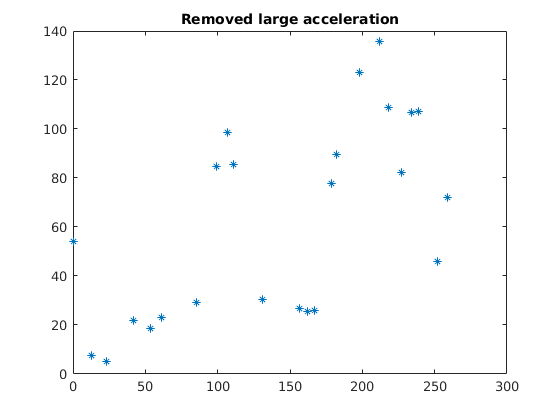

plot(fixed_time_array, fixed_height_array, "*")
title("Removed large acceleration")

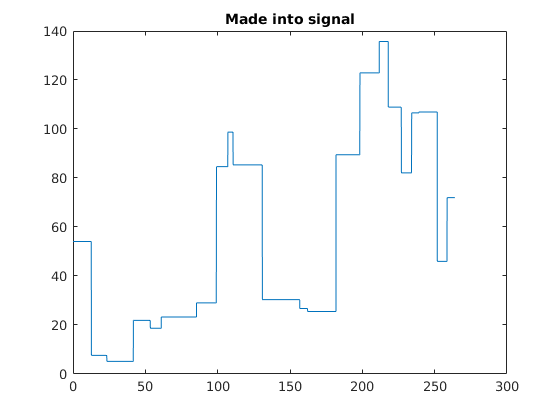

[flightReg_time, flightReg_DesiredHeight] = get_flight_regime(fixed_time_array, ...
                                                              fixed_height_array, ...
                                                              sampleT, ...
                                                              flightReg_finalT(i));

%plot(flightReg_time, flightReg_DesiredHeight, "*")
%title("Made into signal")
plot(flightReg_time, flightReg_DesiredHeight)
title("Made into signal")

#### Functions

function [track_error] = getPerformance(desiredH_arr, realH_arr)
    track_error = mean( (desiredH_arr - realH_arr).^2 );        % Mean square-error
end

function [fixed_time_array, fixed_height_array] = remove_large_vel(time_array, height_array, vel_limit)
    % Starting conditions
    prev_t = time_array(1);
    prev_h = height_array(1);
    prev_vel = 0;
    
    undone = true;
    i = 2;
    
    while (undone)
        
        %fprintf("i: %d\n",i);
        curr_t = time_array(i);
        curr_h = height_array(i);
        
        curr_vel = (curr_h - prev_h) / (curr_t - prev_t);
        %curr_a = (curr_vel - prev_vel) / (curr_t - prev_t);
        
        % used to be acceleration limit
        % if (abs(curr_a) > accel_limit)
        if (abs(curr_vel) > vel_limit)
            time_array(i) = [];
            height_array(i) = [];
            
            %fprintf("Removed idx %d\n", i);
            
            if (i>length(time_array))
                undone = false;
            end
            
            continue;
        end
        
        %fprintf("Idx = %d; velocity = %f; accell = %f\n", i, curr_vel, curr_a);
        
        prev_t = curr_t;
        prev_h = curr_h;
        prev_vel = curr_vel;
        
        i = i + 1;
        
        if (i>length(time_array))
            undone = false;
        end
    end
    
    fixed_time_array = time_array;
    fixed_height_array = height_array;
    
end

function [flightReg_time, flightReg_DesiredHeight] = get_flight_regime(fixed_time_array, fixed_height_array, sampleT, flight_length)
    flightReg_time = [0:sampleT:flight_length];
    flightReg_DesiredHeight = zeros(1,length(flightReg_time));
    
    step_h = fixed_height_array(1);
    for k = 1:length(flightReg_time)
        
        flightReg_DesiredHeight(k) = step_h;
        
        if ismember(flightReg_time(k), fixed_time_array)
            idx = find(fixed_time_array==flightReg_time(k));
            step_h = fixed_height_array(idx);
        end
        
    end
end